# Respuesta en frecuencia y auralización de las señales

#### Respuestas en frecuencia

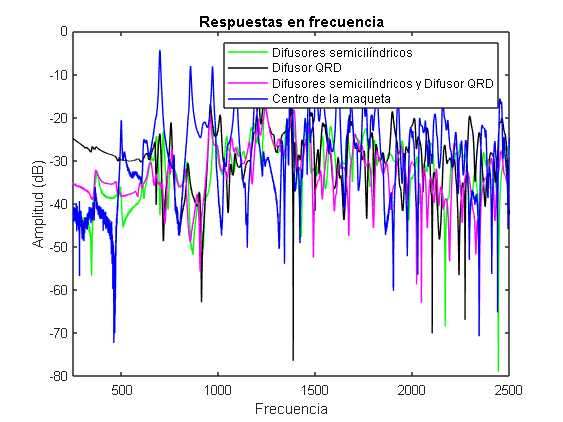

% Lectura de las 3 respuestas al impulso
[hS,fs_hS] = audioread("hsemic.wav"); % Difusores semicilíndricos en los laterales
[hQ,fs_hQ] = audioread("hQRD.wav"); % Difusor QRD en la parte trasera
[hSQ,fs_hSQ] = audioread("hQRDysemic.wav"); % Difusor QRD en la parte trasera + Difusores semicilíndricos en los laterales
[centro1, fs_centro] = audioread('centro1.wav');

% Puntos de la FFT (potencia de 2 más cercana por arriba a la longitud de cada señal)
N_S = 2^ceil(log2(length(hS)));
N_Q = 2^ceil(log2(length(hQ)));
N_SQ = 2^ceil(log2(length(hSQ)));
numero_pts_centro = 2^ceil(log2(length(centro1))); 

%Cálculo de las respuestas en frecuencia (FFT de las respuestas al impulso)
ft_S = fft(hS,N_S);
ft_Q = fft(hQ,N_Q);
ft_SQ = fft(hSQ,N_SQ);
fft_centro = fft(centro1,numero_pts_centro);

% Vectores para la representación
S_ft = fs_hS*(0:(N_S-1))/N_S;
Q_ft = fs_hQ*(0:(N_Q-1))/N_Q;
SQ_ft = fs_hSQ*(0:(N_SQ-1))/N_SQ;
x_c = fs_centro*(0:(numero_pts_centro-1))/numero_pts_centro;

% Convertir la amplitud a dB
dB_S = 20*log10(abs(ft_S)/max(abs(ft_S)));
dB_Q = 20*log10(abs(ft_Q)/max(abs(ft_Q)));
dB_SQ = 20*log10(abs(ft_SQ)/max(abs(ft_Q)));
dB_centro = 20*log10(abs(fft_centro)/max(abs(fft_centro)));

% Representación
figure
plot(S_ft,dB_S,'g');
hold on
plot(Q_ft,dB_Q,'k');
hold on
plot(SQ_ft,dB_SQ,'m');
hold on
plot(x_c,dB_centro,'b');
xlim([250, 2500]);
xlabel("Frecuencia");
ylabel("Amplitud (dB)");
title('Respuestas en frecuencia');
legend("Difusores semicilíndricos","Difusor QRD","Difusores semicilíndricos y Difusor QRD","Centro de la maqueta")

#### Auralización de las señales

% Lectura de las señales de bajo
[bajoSemic, fs_bajoSemic] = audioread("bajo semic.wav");
[bajoQRD, fs_bajoQRD] = audioread("bajoQRD.wav");
[bajoSemicQRD, fs_bajoSemicQRD] = audioread("bajoqrd_semic.wav");
[bajo_rapido, fs_rapida]=audioread("svacia.wav");

% Escalar la respuesta al impulso del modelo a la escala real
Semic_diezmada = decimate(hS,10);
QRD_diezmada = decimate(hQ,10);
SemicQRD_diezmada = decimate(hSQ,10);

% Convolucionar la señal real con la respuesta al impulso escalada.
Semic_diezmada_conv = conv(bajoSemic(:,1),Semic_diezmada);
QRD_diezmada_conv = conv(bajoQRD,QRD_diezmada);
SemicQRD_diezmada_conv = conv(bajoSemicQRD,SemicQRD_diezmada);
bajo_interpolado=interp(bajo_rapido,10);

% Normalizar las señales para que el valor máximo sea ±1
Semic_diezmada_conv = Semic_diezmada_conv / max(abs(Semic_diezmada_conv));
QRD_diezmada_conv = QRD_diezmada_conv / max(abs(QRD_diezmada_conv));
SemicQRD_diezmada_conv = SemicQRD_diezmada_conv / max(abs(SemicQRD_diezmada_conv));
bajo_interpolado = bajo_interpolado / max(abs(bajo_interpolado));

% Escribir los archivos de audio
audiowrite("Semic_conv.wav", Semic_diezmada_conv, fs_bajoSemic/10);
audiowrite("QRD_conv.wav", QRD_diezmada_conv, fs_bajoQRD/10);
audiowrite("SemicQRD_conv.wav", SemicQRD_diezmada_conv, fs_bajoSemicQRD/10);
audiowrite("bajo_interpolado.wav", bajo_interpolado, fs_rapida);

%---------- Eliminar comentarios para poder reproducir ---------- %
% soundsc(Semic_diezmada_conv,fs_bajoSemic/10);
% soundsc(QRD_diezmada_conv,fs_bajoQRD/10);
% soundsc(SemicQRD_diezmada_conv,fs_bajoSemicQRD/10);
% soundsc(bajo_interpolado,fs_rapida);
% ---------------------------------------------------------------- %
